#### Part I: Tone and Sound Design

1. Tempo, beat and time are crucial elements in music, so first create functions that convert the number of beats, seconds and ticks

The speed at which music is played is called tempo. Tempo is calculated by how many beats per minute or BPM. Thus we often refer to a song as "120 BPM", meaning 120 beats (pulses) per minute". fs means sample rate, i.e. 44,100 consecutive signals make up one second of sound. To make the division of time more precise, we can divide a beat into finer ticks.

For the purposes of this report, the conversion scheme for time and tempo units is:** 1 beat = 60/BPM second = 96 tick**

clear
fs=44100;dt=1/fs;
help beat2time,help freq

 Converting BPM into corresponding note durations and vectors
 Input
  BPM - Beat Per Minute
  c - Note (Input 1/4 if it's a 1/4 note)
 Output
  T - Note duration(s)
  t - Time vector with sampling rate fs from 0 to T

 Returns the frequency according to the midi note
 Input
  midinote - midi note number (e.g. A4 440Hz has a number of 69)



Then we can obtain a sequence of audio signals with a duration of T and a sampling rate of fs:

[T16,t16]=beat2time(50,1/16);
[T1,t1]=beat2time(60,1/2)

T1 = 0.5000

t1 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


help tick2time

  Converts BPM into a vector of durations and times corresponding to notes
 Input
  BPM - Beat Per Minute
  c - Number of Ticks
  unit - ticks every beat
 Output
  T - Time Duration of a note(s)
  t - Time vector with sampling rate fs from 0 to T



2. Synthesise a note by superimposing a function and enveloping the volume.

In order to avoid the phenomenon of popping, we can superimpose a sine wave (the frequency of its fundamental frequency and all levels of overtones, respectively), the volume of a small to large and large to small envelope and make the volume of continuous change, making the note sounds more natural. 

Code implementation:

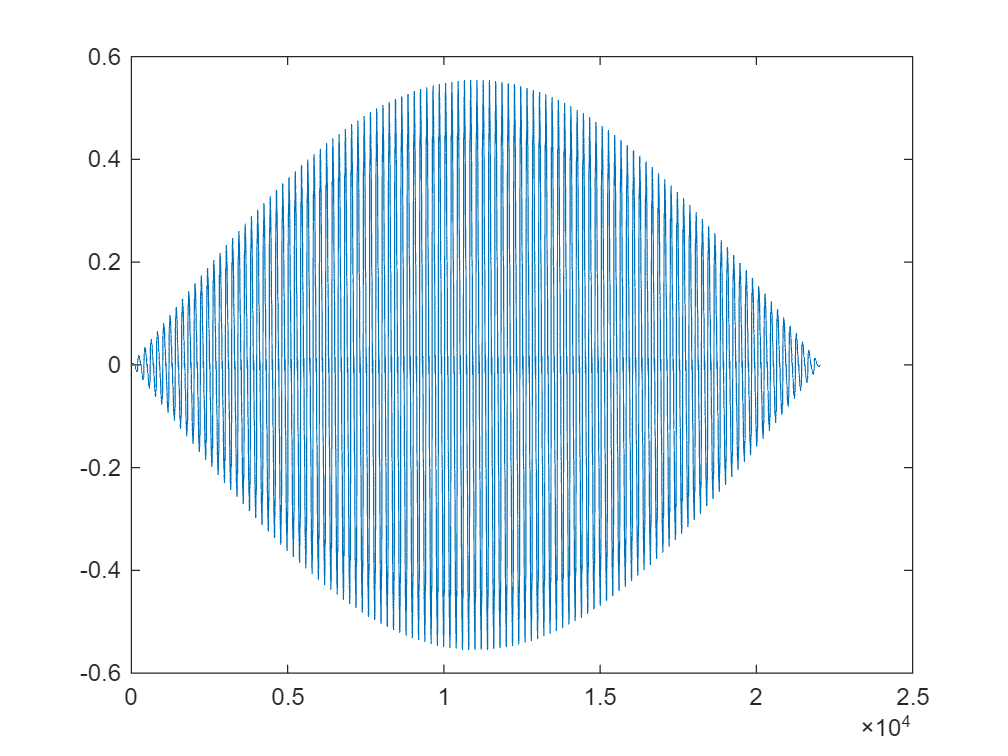

waveFoun=sin(2*pi*freq(57)*t1);%base frequency
velocityHarm=[1 0.341 0.103 0.086 0.071 0.066 0.029 0.086 0.012 0.031 0.011 0.015 0.013 0.014 0.005 0.002];%泛音的比例
for i=2:10
waveHarm{i}=sin(2*pi*freq(57)*i*t1)*velocityHarm(i);
%Overtones are layered on top of the fundamental frequency signal to make the notes sound fuller.
end
Mod=sin(pi*t1/t1(end));
wave=waveFoun;
for i=2:10
    wave=wave+waveHarm{i};
end
noteA=Mod.*(wave)./2;
plot(noteA)

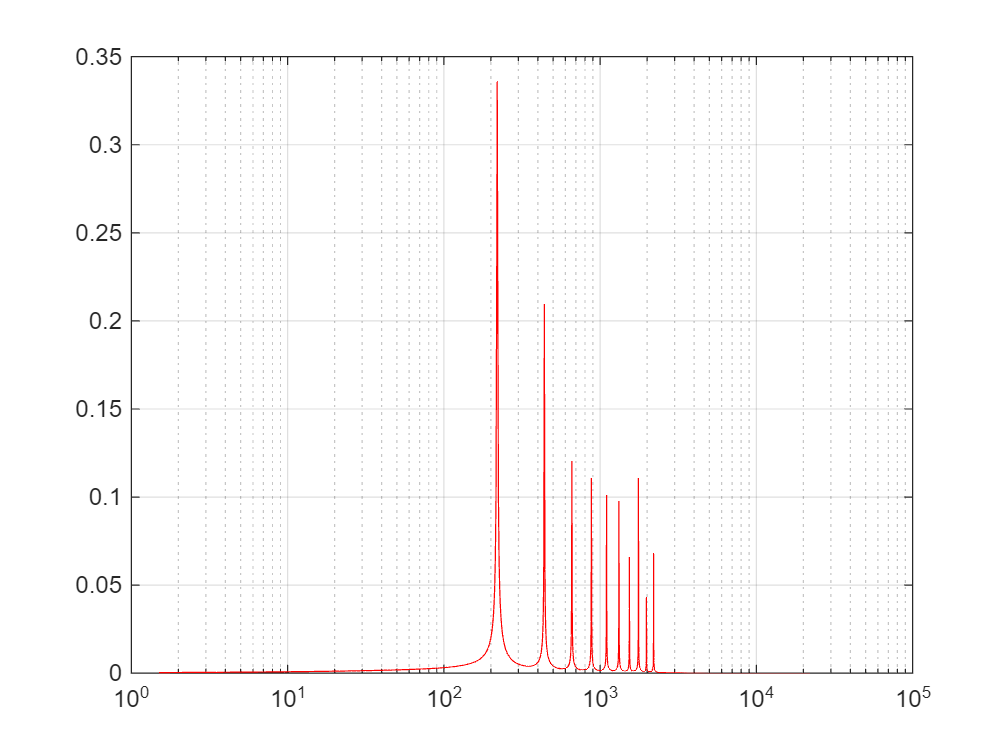

sound(noteA,fs)
x=noteA;
frequency2(x)

It can be seen that the tone is determined by the pitch of the fundamental frequency, while the proportion and amount of overtones determine the difference between fullness and colour of the tone.

3.From the above, it can be found that the timbre can be determined by the waveform (wave) and volume envelope (Mod), so we can build functions to quickly generate notes with different timbres, pitches (pitch), durations (time), and loudness (loudness). 

Code implements:

fs=44100;
wave1=@(x) (0<x).*(x<=1).*(2*x-1);%sawtooth wave
wave2=@(x) (0<x).*(x<=1).*sin(2*pi*x);%sinusoidal wave
wave3=@(x) (0<x).*(x<=0.5)-(0.5<x).*(x<=1);%square wave
wave4=@(x) (0<x).*(x<=1).*(2*rand(1,length(x))-1);%noise
subplot(2,3,1),fplot(wave1,[0 1]),axis([0 1 -2 2]),title('wave1')
subplot(2,3,2),fplot(wave2,[0 1]),axis([0 1 -2 2]),title('wave2')
subplot(2,3,3),fplot(wave3,[0 1]),axis([0 1 -2 2]),title('wave3')
Mod1=@(x) sin(pi*x); 
Attack=1;Decay=1;Sustain=5;Release=0.1; 
Max=1;Amplitude=0.7;
Time=Attack+Decay+Sustain+Release;
tt=cumsum([Time.\Attack Time.\Decay Time.\Sustain Time.\Release]);
Mod2=@(x) (0<x).*(x<=tt(1)).*Max./tt(1).*x...
    +(tt(1)<x).*(x<=tt(2)).*((Amplitude-Max)/(tt(2)-tt(1)).*(x-tt(1))+Max)...
    +(tt(2)<x).*(x<=tt(3)).*Amplitude...
    +(tt(3)<x).*(x<=tt(4)).*((-Amplitude)/(tt(4)-tt(3)).*(x-tt(3))+Amplitude)

Mod2 = 包含以下值的 function_handle :
    @(x)(0<x).*(x<=tt(1)).*Max./tt(1).*x+(tt(1)<x).*(x<=tt(2)).*((Amplitude-Max)/(tt(2)-tt(1)).*(x-tt(1))+Max)+(tt(2)<x).*(x<=tt(3)).*Amplitude+(tt(3)<x).*(x<=tt(4)).*((-Amplitude)/(tt(4)-tt(3)).*(x-tt(3))+Amplitude)

Attack=3;Decay=2;Sustain=5;Release=1;
Max=1;Amplitude=0.5;
Time=Attack+Decay+Sustain+Release;
tt=cumsum([Time.\Attack Time.\Decay Time.\Sustain Time.\Release]);
Mod3=@(x) (0<x).*(x<=tt(1)).*Max./tt(1).*x...
    +(tt(1)<x).*(x<=tt(2)).*((Amplitude-Max)/(tt(2)-tt(1)).*(x-tt(1))+Max)...
    +(tt(2)<x).*(x<=tt(3)).*Amplitude...
    +(tt(3)<x).*(x<=tt(4)).*((-Amplitude)/(tt(4)-tt(3)).*(x-tt(3))+Amplitude)

Mod3 = 包含以下值的 function_handle :
    @(x)(0<x).*(x<=tt(1)).*Max./tt(1).*x+(tt(1)<x).*(x<=tt(2)).*((Amplitude-Max)/(tt(2)-tt(1)).*(x-tt(1))+Max)+(tt(2)<x).*(x<=tt(3)).*Amplitude+(tt(3)<x).*(x<=tt(4)).*((-Amplitude)/(tt(4)-tt(3)).*(x-tt(3))+Amplitude)

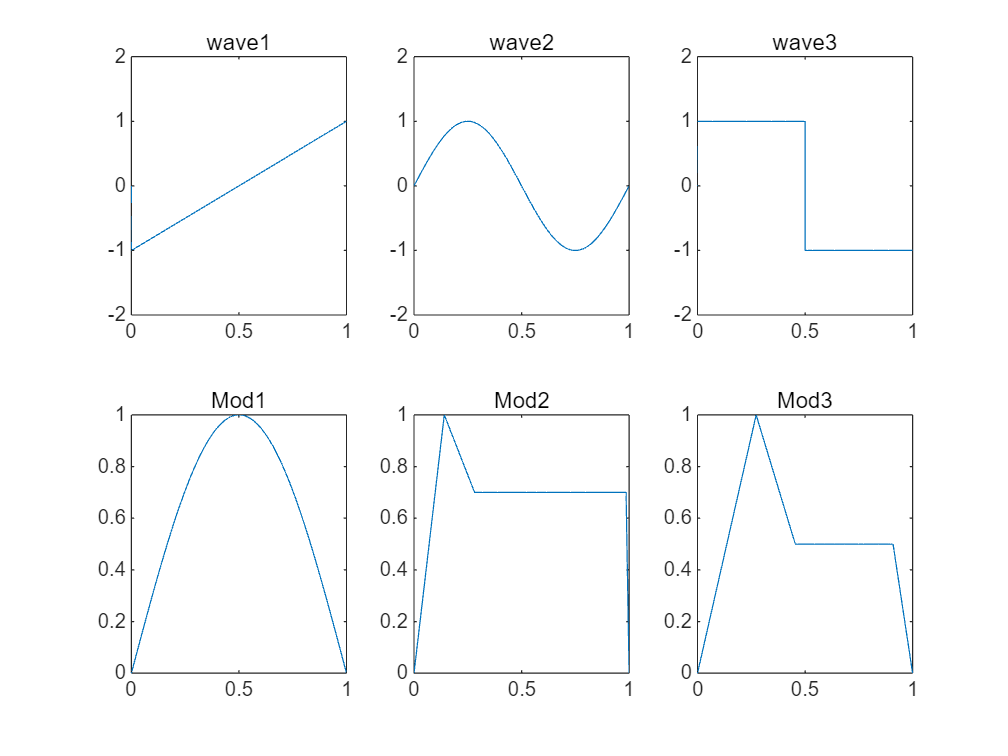

subplot(2,3,4),fplot(Mod1,[0 1]),axis([0 1 0 1]),title('Mod1')
subplot(2,3,5),fplot(Mod2,[0 1]),axis([0 1 0 1]),title('Mod2')
subplot(2,3,6),fplot(Mod3,[0 1]),axis([0 1 0 1]),title('Mod3')

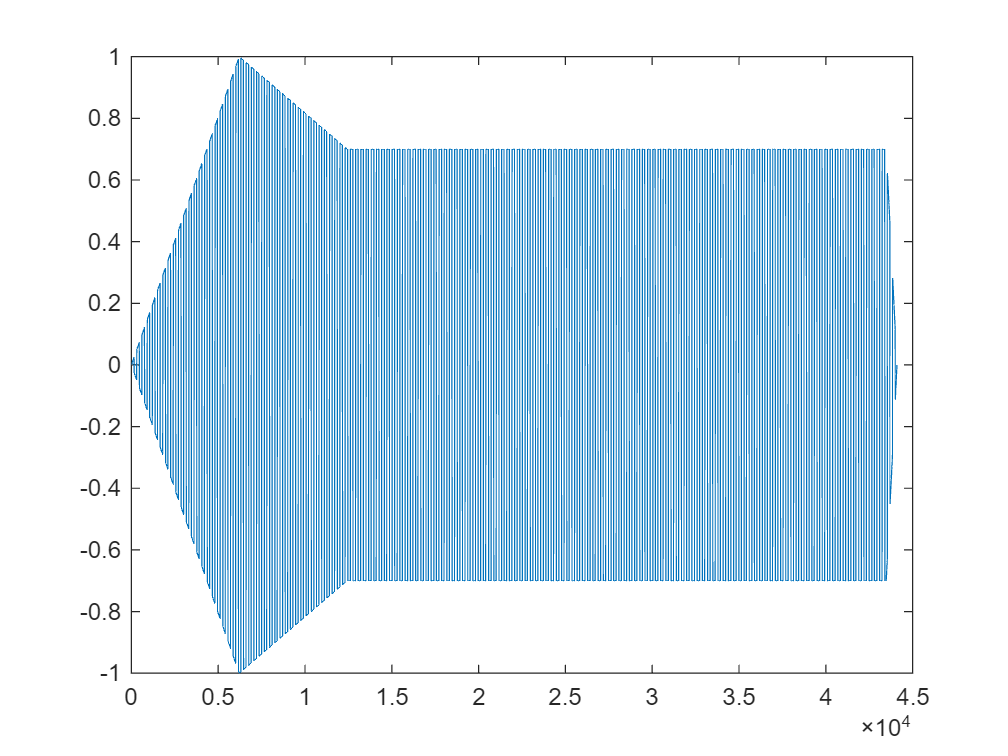

[T,time]=beat2time(60,1);
midinote=50;%Setting the Pitch
note=zeros(1,length(time));
for t=1:length(time)
    note(t)=wave3(freq(midinote)*mod(time(t),1/freq(midinote)));%Copy Shape
end
note=note.*Mod2(time./T);%volume envelope
clf,plot(note)

sound(note./5,fs)

(1) Create a function to generate the volume envelope.

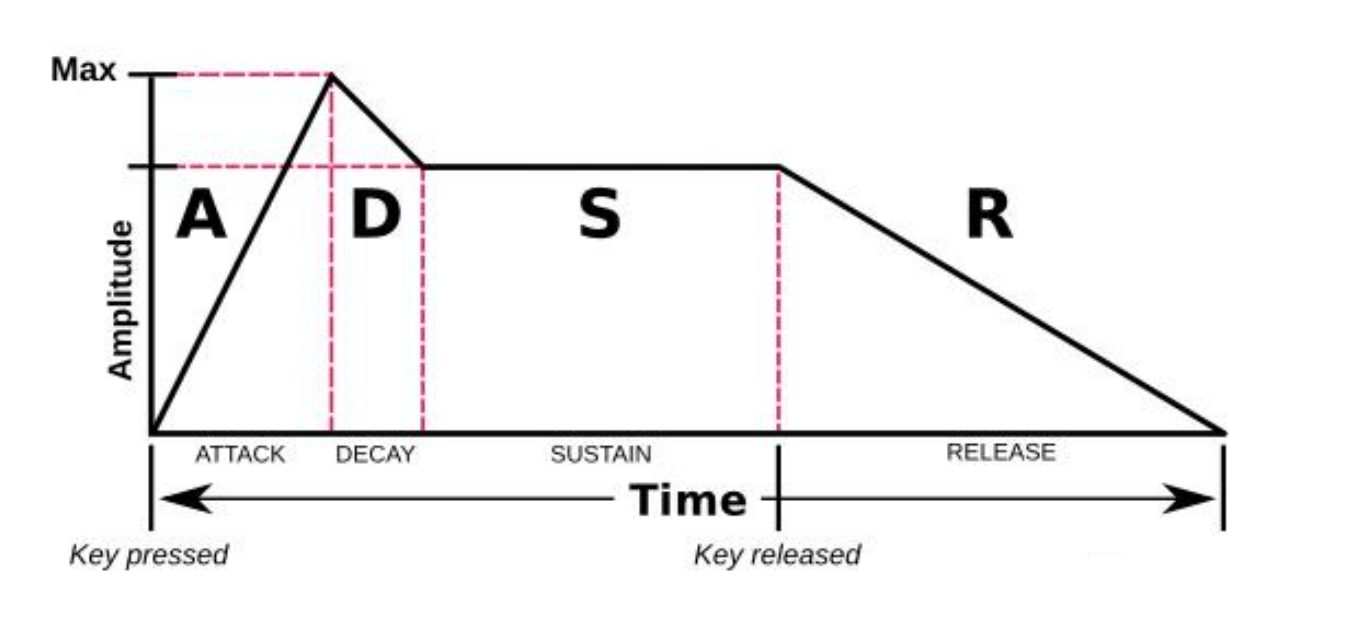

 help ADSR1,help ADSR2

 Note ADSR envelope function
 Input
  Attack - attack time
  Decay - decay time
  Sustain - sustain time
  Release - release time
  Max - peak
  Amplitude - size of amplitude

 Note ADSR envelope function
 Input
  Attack - attack time
  Decay - decay time
  Sustain - sustain time
  Release - release time
  Max - peak
  Amplitude - size of amplitude
  n - decay factor



 help fnote

 note generator
 Input
  pitch - （midinote）
  time - (s)
  wave - waveform
  Mod - volume envelope
  loudness - (%)



Create functions to generate notes:

Mod3=ADSR2(1,1,1,1,1,0.7,20);

Combining different waveforms and envelopes can generate different timbres.

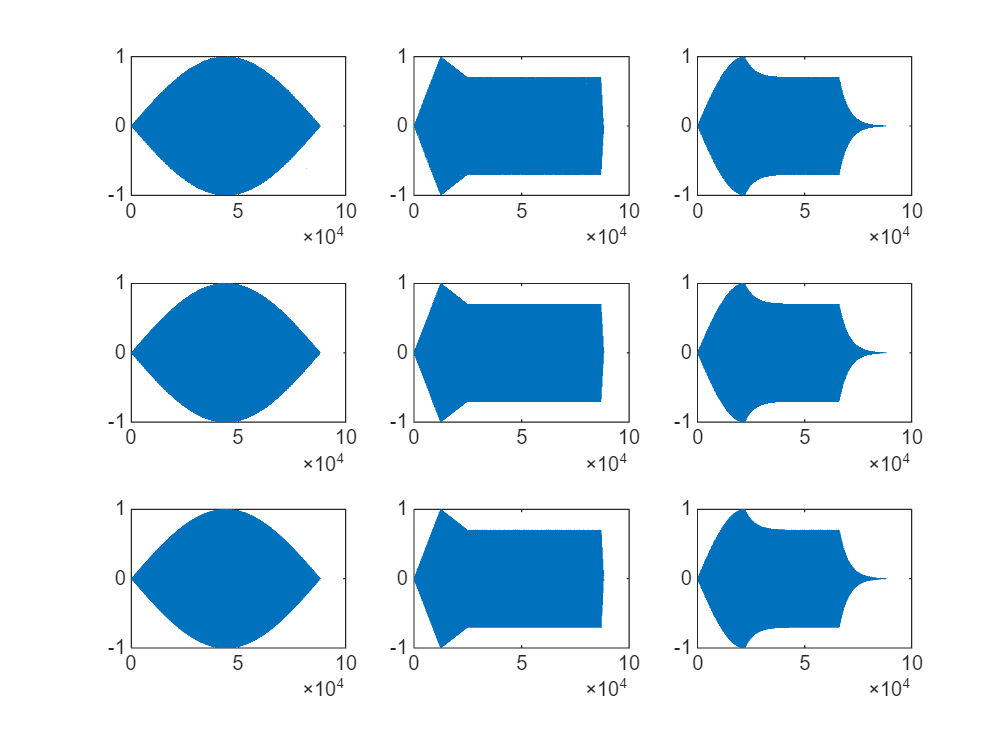

waves={wave1,wave2,wave3};
Mods={Mod1,Mod2,Mod3};
for i=1:3
    for j=1:3
A=fnote(50,2,waves{i},Mods{j},1);
subplot(3,3,3*i+j-3),plot(A)
    end
end

These are the different notes generated by combining volume envelopes and waveforms

generating a timbre:

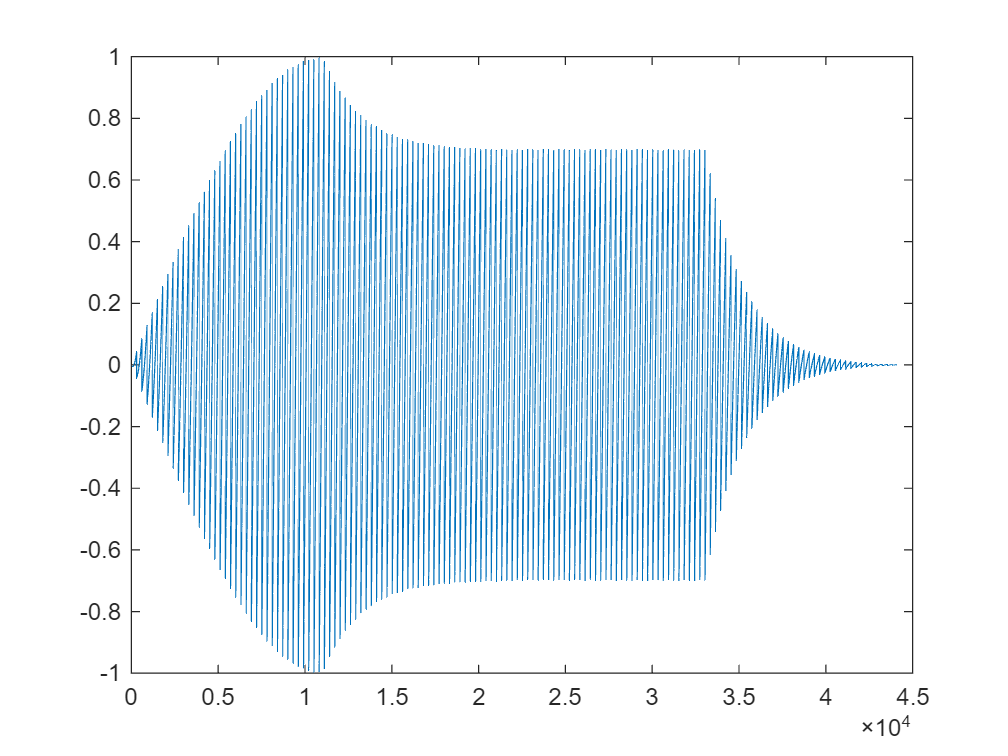

%mm=ADSR2(1,1,1,1,1,0.7,20);
s=fnote(50,1,waves{1},Mods{3},1);sound(s./2,fs),clf,plot(s)

Once you have a method for generating notes, you can design the desired timbre. We need to design the timbre according to the frequency characteristics and timbre features of different instruments and sound effects.

4. Making drum tones

(1) Making the Kick Drum Tone

Characteristics: sense of power, concentrated energy, low-frequency signal-based

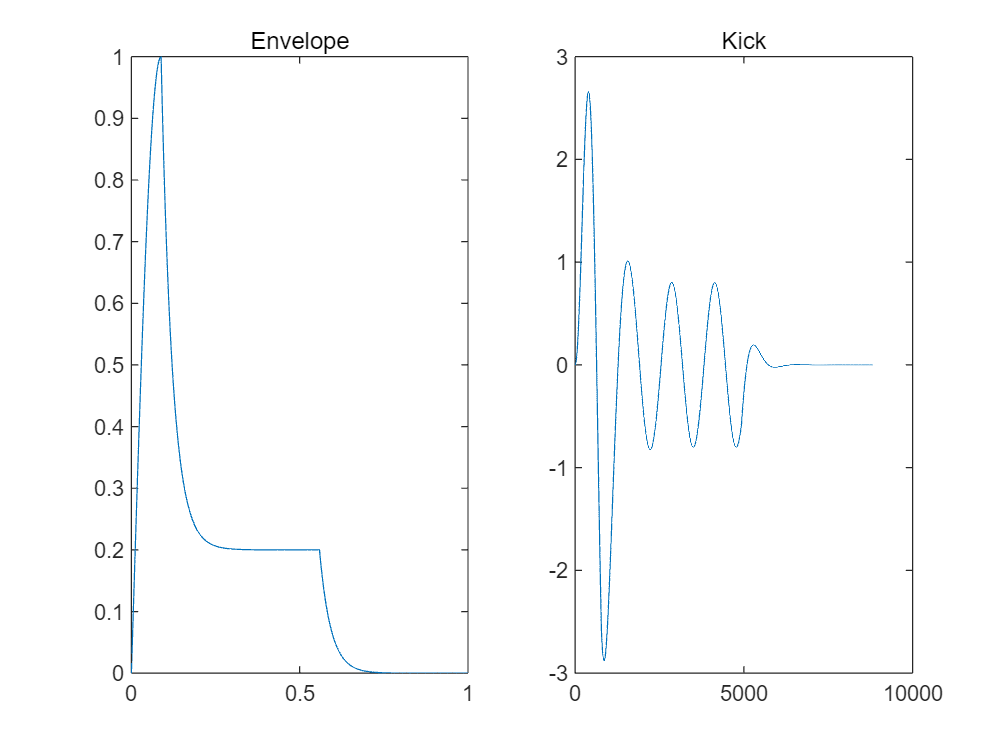

Mod=ADSR2(3,15,1,15,1,0.2,30);%Setting a shorter Attack time for a slamming feel
clf,subplot(1,2,1),fplot(Mod,[0,1]),title('Envelope')
Kick=fnote(25,0.2,wave2,Mod,4);%Setting a relatively low tone with a duration of 0.2s, simulated with a sine wave
subplot(1,2,2),plot(Kick),title('Kick')

Hook up the compressor: 

(see part 2 for compressor design)

KickCompressor=compressor

KickCompressor =   compressor - 属性:

          Threshold: -10
              Ratio: 5
          KneeWidth: 0
         AttackTime: 0.0500
        ReleaseTime: 0.2000
     MakeUpGainMode: 'Property'
         MakeUpGain: 0
    EnableSidechain: false
         SampleRate: 44100

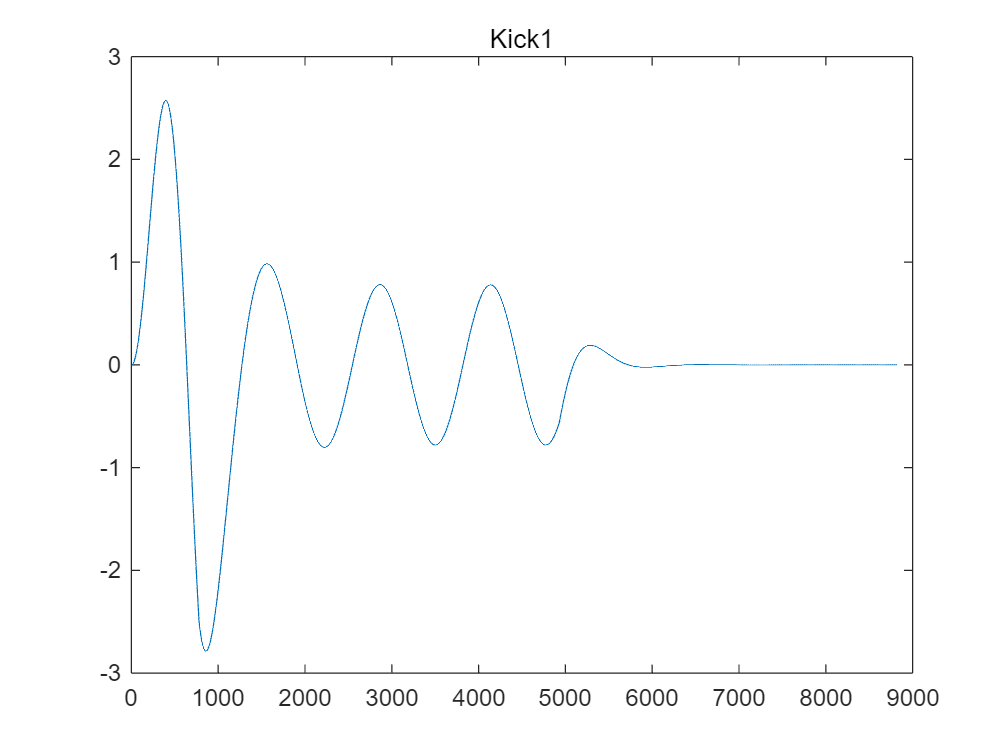

KickCompressor.Threshold=-50;
KickCompressor.Ratio=40;
KickCompressor.AttackTime=0.01;
Kick=KickCompressor(Kick);
clf,plot(Kick),title('Kick1')

sound(Kick,fs)
Kick=Kick./max(abs(Kick(:)));

Basically it already sounds like a bottom drum, but it's obvious that the sound is too weak and lacks energy. 

To make the bottom drum feel more powerful, make a pitch change note.

Functions that generate notes with continuously changing pitch

help fnote2,help fnote3

 Note generator (linear change of pitch)
 Input
  pitch - （midinote）
  time - (s)
  wave - waveform
  Mod - volume envelope
  loudness - (%)

 Note generator (exponential change of pitch)
 Input
  pitch - （midinote）
  time - (s)
  wave - waveform
  Mod - volume envelope
  loudness - (%)



Mod=ADSR2(0.1,1,1,1,1,0.5,50);
note1=fnote2([50 10],0.5,wave2,Mod,1);
%Notes whose pitch changes continuously from D4 to bB0 with a duration of 0.5s, simulated with a sine wave
note2=fnote2([90 50],0.5,wave2,Mod,1)

note2 =          0    0.0005    0.0018    0.0039    0.0066    0.0096    0.0126    0.0154    0.0176    0.0188    0.0190    0.0178    0.0153    0.0113    0.0060   -0.0005   -0.0079   -0.0159   -0.0239   -0.0317   -0.0387   -0.0444   -0.0484   -0.0504   -0.0500   -0.0472   -0.0418   -0.0339   -0.0239   -0.0119    0.0015    0.0157    0.0302    0.0441    0.0569    0.0677    0.0761    0.0813    0.0831    0.0812    0.0754    0.0659    0.0529    0.0368    0.0183   -0.0019   -0.0229   -0.0438   -0.0637   -0.0815


%sound(note1,fs)
C1=compressor

C1 =   compressor - 属性:

          Threshold: -10
              Ratio: 5
          KneeWidth: 0
         AttackTime: 0.0500
        ReleaseTime: 0.2000
     MakeUpGainMode: 'Property'
         MakeUpGain: 0
    EnableSidechain: false
         SampleRate: 44100

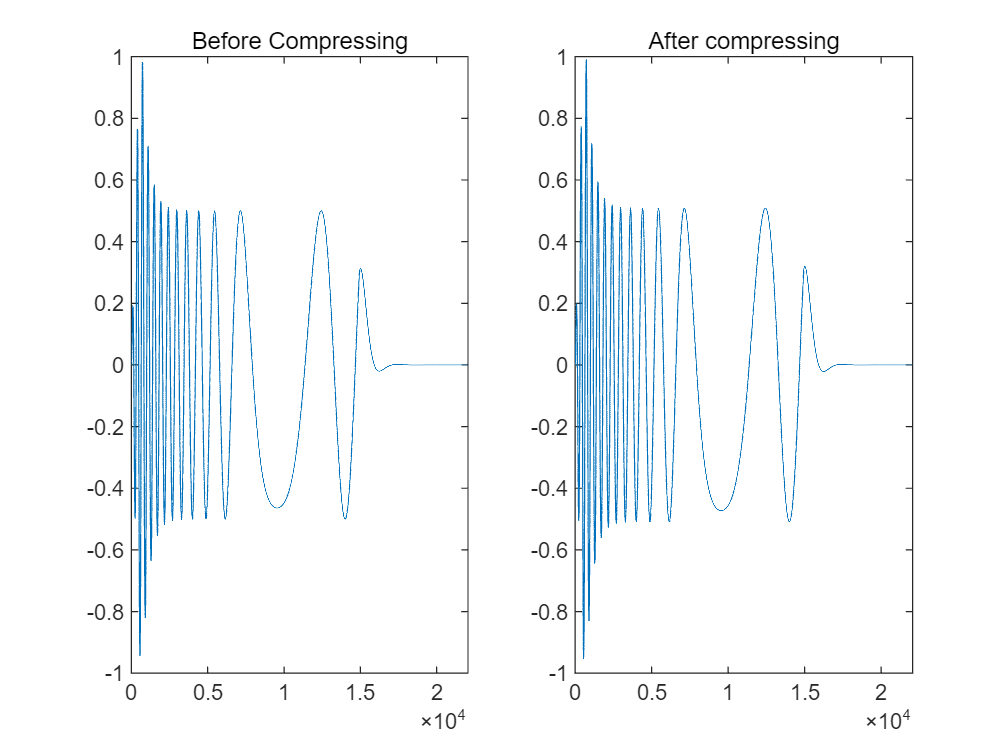

C1.Ratio=50;
C1.Threshold=-35;
C1.AttackTime=0.004;
C1.MakeUpGain=0.5;
subplot(1,2,1),plot(note1),title('Before Compressing')
Kick=C1(note1);
subplot(1,2,2),plot(Kick),title('After compressing')

With the use of continuously changing notes and compression, the high-frequency signal of the bottom drum tone is seen to be concentrated in the head, with the energy diminishing over time.

sound(Kick,44100)
%audiowrite("Kick.wav",Kick,fs)

(2) Creating the Hats Sound

Characteristics: High-frequency signals, short bursts of time, and a "bared" sound.

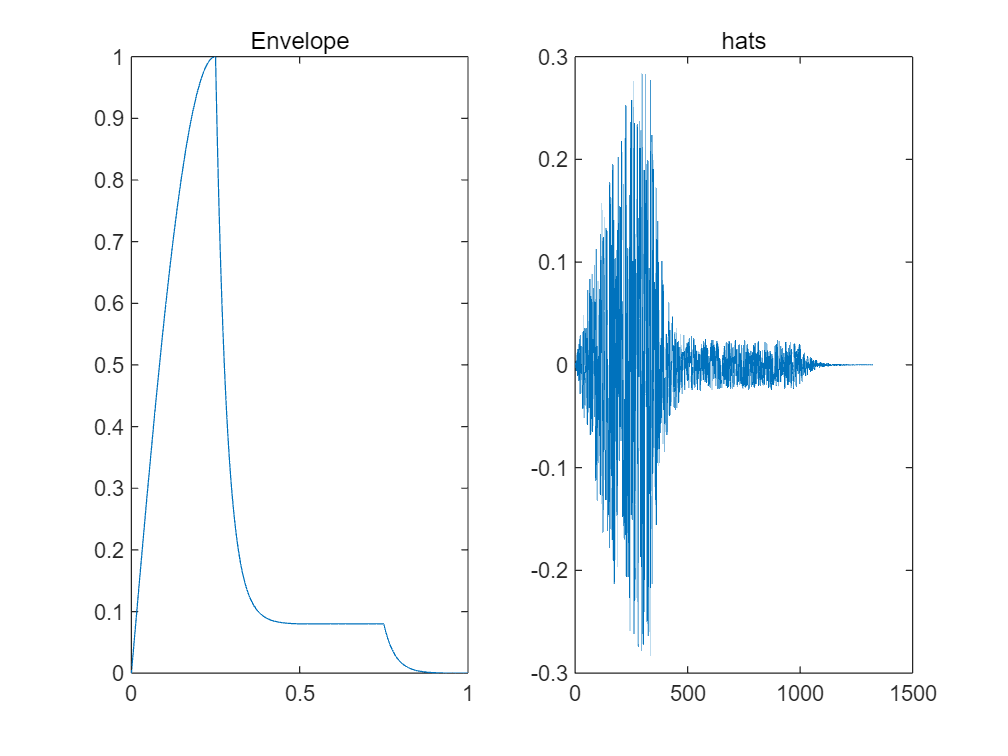

rng default
Mod4=ADSR2(1,1,1,1,1,0.08,30);
clf,subplot(1,2,1),fplot(Mod4,[0,1]),title('Envelope')
hats=fnote(400,0.03,wave4,Mod4,0.3);
%Set high-frequency signal (but not useful because it's noise), duration 0.03s

subplot(1,2,2),plot(hats),title('hats')

sound(hats,fs)
%audiowrite("hats.wav",hats,fs)

(3) Making a Snare Drum Tone

Characteristics: Percussive and fierce

rng default
wave5=@(x) wave2(x)+wave1(x)./5+wave4(x)./4;
% A mixture of sine waves, sawtooth waves and noise,
% the latter simulating the rustling sound of a drum's membrane vibrating when it is struck.

Mod5=ADSR2(0.3,5,0.1,15,1,0.4,20);
clf,subplot(1,2,1),fplot(Mod5,[0,1]),title('Envelope')
Snare=fnote(50,0.15,wave5,Mod5,2);
Snarecompressor=compressor

Snarecompressor =   compressor - 属性:

          Threshold: -10
              Ratio: 5
          KneeWidth: 0
         AttackTime: 0.0500
        ReleaseTime: 0.2000
     MakeUpGainMode: 'Property'
         MakeUpGain: 0
    EnableSidechain: false
         SampleRate: 44100

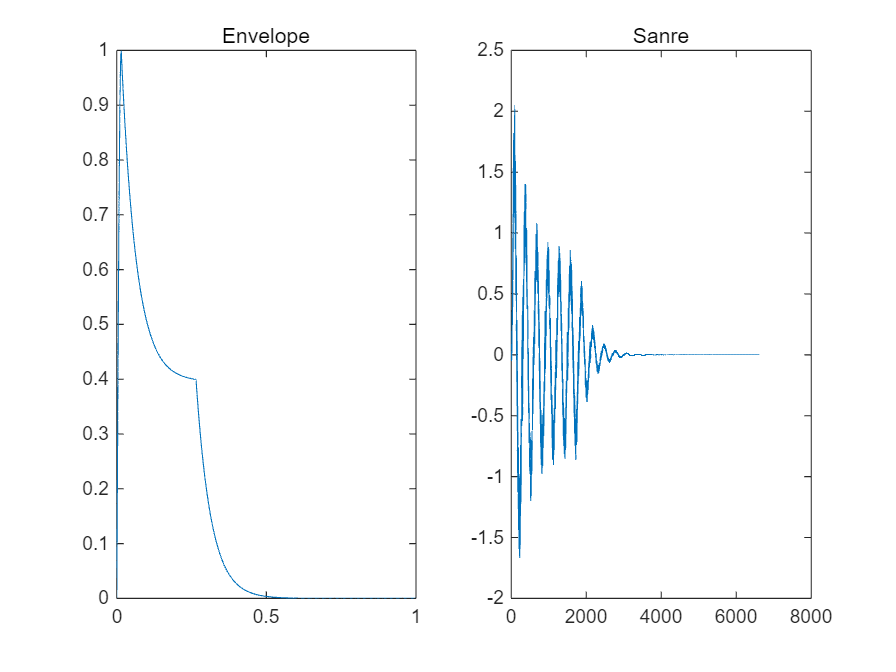

Snarecompressor.Threshold=-400;
Snarecompressor.AttackTime=0.04;
Snarecompressor.Ratio=10;
Snare=Snarecompressor(Snare);
subplot(1,2,2),plot(Snare),title('Sanre')

sound(Snare,fs)
Snare=Snare./max(abs(Snare(:)));
%("Snare.wav",Snare,fs)

We've created the basic tones of the drum kit, next create the synth-like electronic tones.

5. Design pluck tone

Characteristics: Crisp, short sound

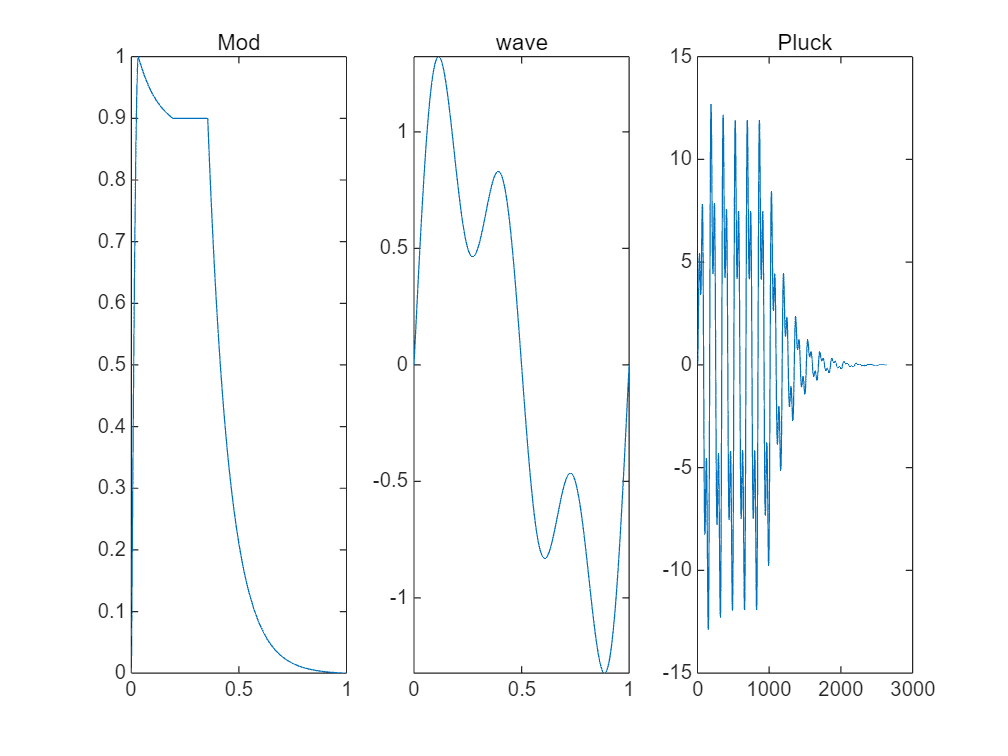

Mod=ADSR2(1,5,5,20,1,0.9,10);
clf,subplot(1,3,1),fplot(Mod,[0,1]),title('Mod')
wave=@(x) (0<x).*(x<=1).*(sin(2*pi*x)+sin(4*pi*x)./4+sin(6*pi*x)./2);
% Drawing a strange waveform

subplot(1,3,2),fplot(wave,[0,1]),title('wave')
pluck=fnote(60,0.06,wave,Mod,10);
sound(pluck,fs)
subplot(1,3,3),plot(pluck),title('Pluck')

6. Creating Sound Effects

Riser sound effect with a gradual increase in pitch.

riser=fnote2([50 70],20,wave2,@(x) 1,1);
%sound(riser,fs)

Piano Reversal Sound

ss=audioread("钢琴 88\German Concert D 060 083.wav");
reverbP=reverberator;;
reversePiano=flip(reverbP(ss))';
sound(reversePiano,fs)

7. Making a LEAD tone

Characteristics: intense, prominent, lead instrument in the chorus

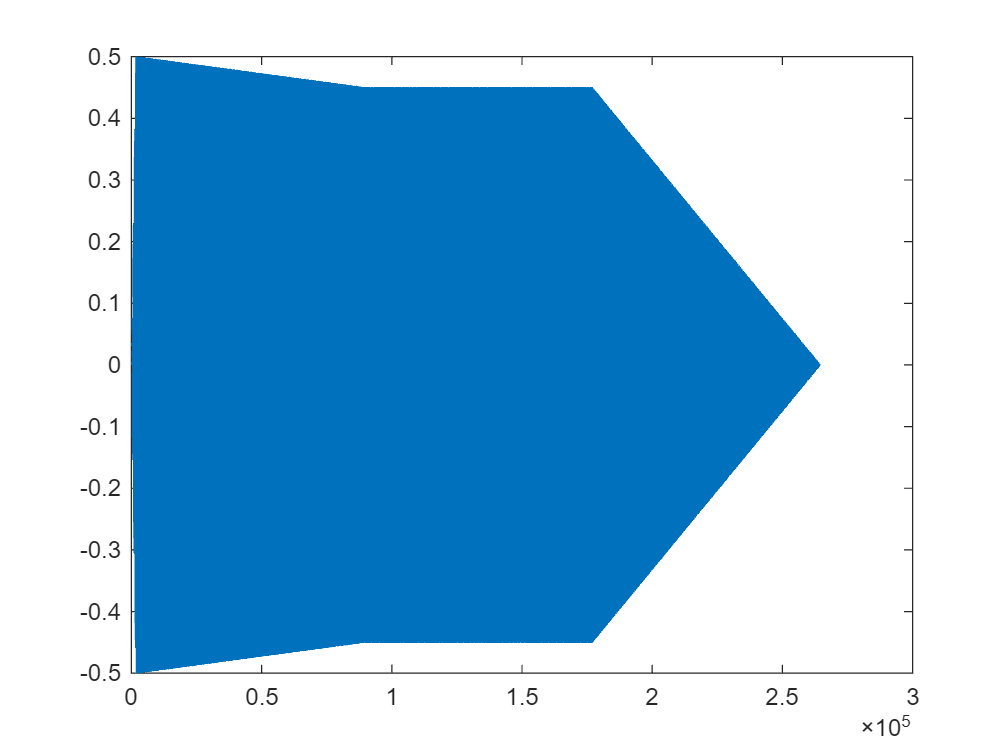

Mod=ADSR1(0.1,5,5,5,1,0.9);
Lead=fnote(40,6,wave3,Mod,0.5);
clf,plot(Lead)

% sound(Lead,fs)

8. Drawing a tone by hand

In addition to generating specific waveforms with functions, you can also use Matlab's toolbox of curve fitting to generate waveforms.

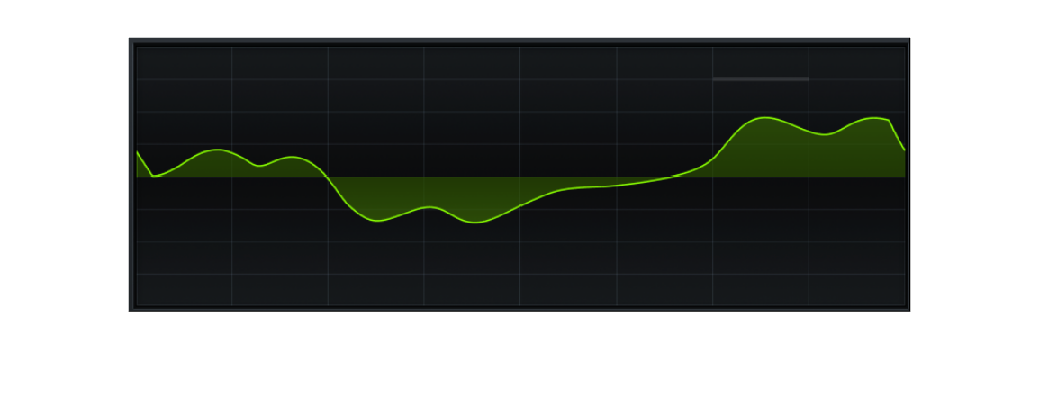

clf
wavepic=imread('data\waveLead.png');
I=imshow(wavepic);
hold on;  
%[x, y]=ginput(100);
hold off

(Waveforms provided by the  serum synthesiser)

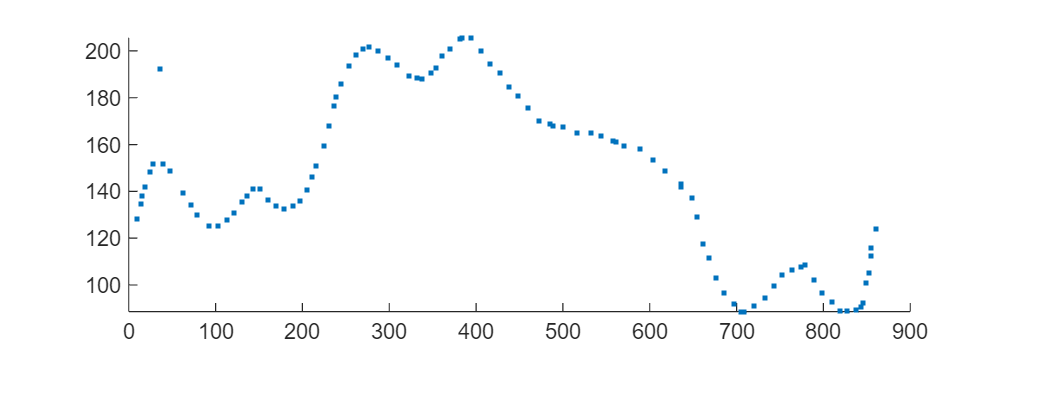

%save("GinputWave.mat","x","y")
load("files\GinputWave.mat")
scatter(x,y,'.')

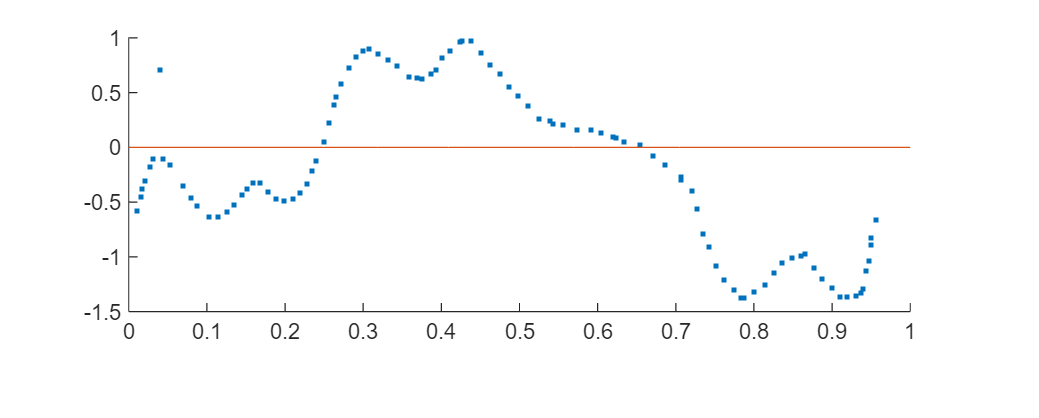

xx=x/900;
yy=(y-157)/50;
scatter(xx,yy,'.'),hold on,fplot(0,[0,1]),hold off

%cftool(xx,yy)

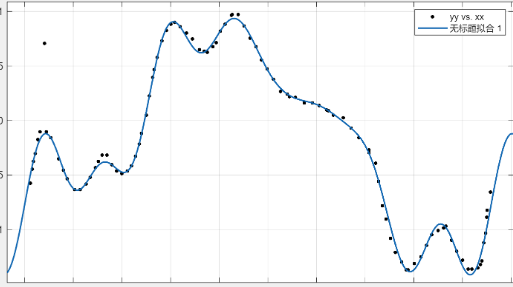

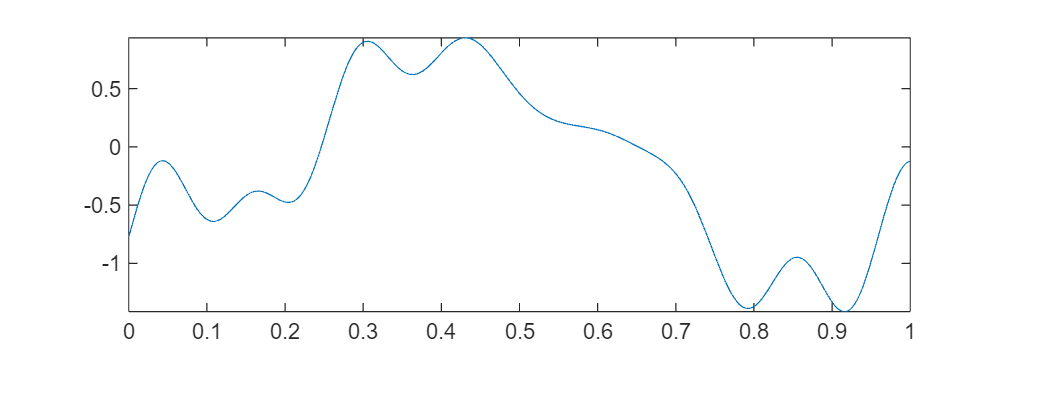

a0=-0.1752;a1=-0.8246;b1=0.4136;a2=0.0984;b2=0.0308;a3=0.2086;b3=0.1582;a4=0.0187;b4=0.0539;a5=-0.1374;b5=0.0766;a6=0.0101;b6=0.0480;a7=0.0478;b7=0.1839;a8=-0.0197;b8=0.0732;w=6.5529 ;
waveLead=@(x) a0 + a1*cos(x*w) + b1*sin(x*w) + a2*cos(2*x*w) + b2*sin(2*x*w) + a3*cos(3*x*w) + b3*sin(3*x*w) + a4*cos(4*x*w) + b4*sin(4*x*w) + a5*cos(5*x*w) + b5*sin(5*x*w) + a6*cos(6*x*w) + b6*sin(6*x*w) + a7*cos(7*x*w) + b7*sin(7*x*w) + a8*cos(8*x*w) + b8*sin(8*x*w);
fplot(waveLead,[0,1])

clear Lead
Lead{133}=0;
Mod=ADSR1(0.1,5,5,5,1,0.9);
for pitch=50:50
Lead{pitch}=fnote(pitch-24,5,waveLead,Mod,0.5)+fnote(pitch-12,5,wave3,Mod,0.5)/2+fnote(pitch,5,wave3,Mod,0.5)/2;
end
sound(Lead{50},fs)

**Part II: Mixing and effects design**

During the mixing process, the frequency, dynamics, reverb and soundstage of each original sound signal are adjusted through various effects to optimise the parameters of each track, which are then superimposed into the final music or audio product. Through the mixing process, the finished product can be layered to achieve the perfect musical effect. Matlab allows you to design different kinds of effects.

1. Delay effect (Delay)

Characteristics: similar to the echo effect, creating a bouncing feeling

help Delay

 Delay
    the length of the genarate signal will be extented
 Input
  s - Original Signal
  delaytime - （beat）
  BPM - Beat Per Minute
  times - echoes times
  n - decay factor
 Outout
  s1 - siganl processed
  d - each signal of the echoes

    Delay 的其他用法



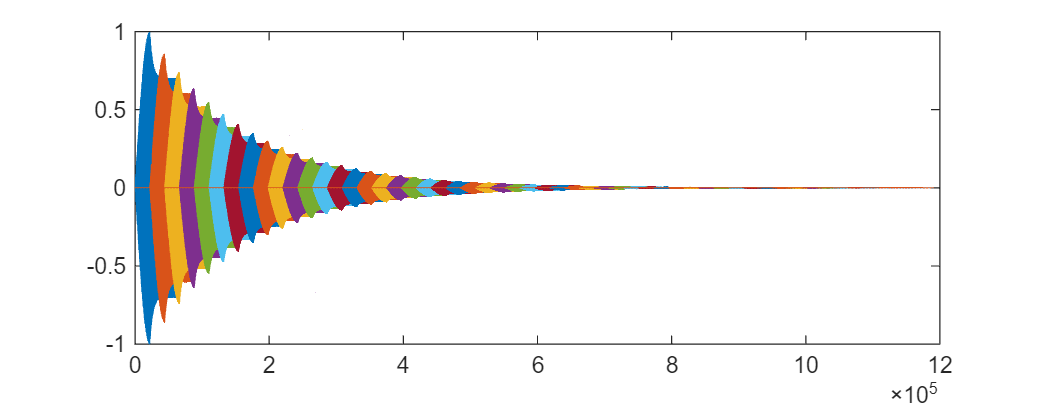

clf,clear
fs=44100;
s=fnote(50,2,@(x) (0<x).*(x<=1).*(2*x-1),ADSR2(1,1,1,1,1,0.7,20),1);
[delays,d]=Delay(s,1/2,60,50,0.15);
plot(s),hold on
for i=1:50
    plot(d{i})
end
hold off

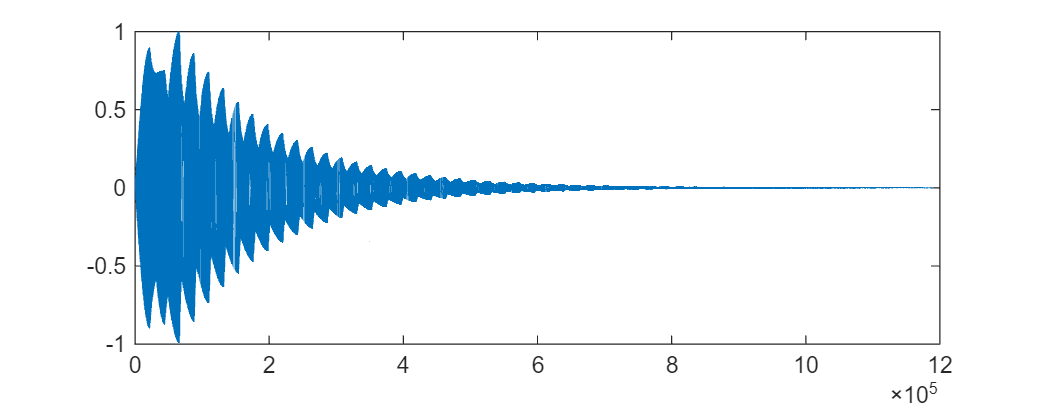

delays=delays/max(delays(:));
plot(delays)

% sound(delays/2,fs)

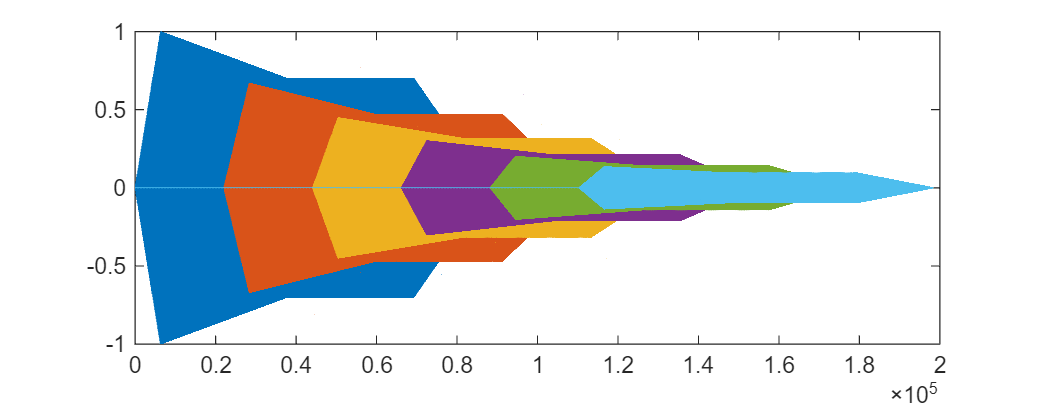

clear s delays d,clf
s=fnote(65,2,@(x) (0<x).*(x<=1).*sin(2*pi*x),ADSR1(1,5,5,3,1,0.7),1);
[delays,d]=Delay(s,1/2,60,5,0.4);
plot(s),hold on
for i=1:5
    plot(d{i})
end
hold off

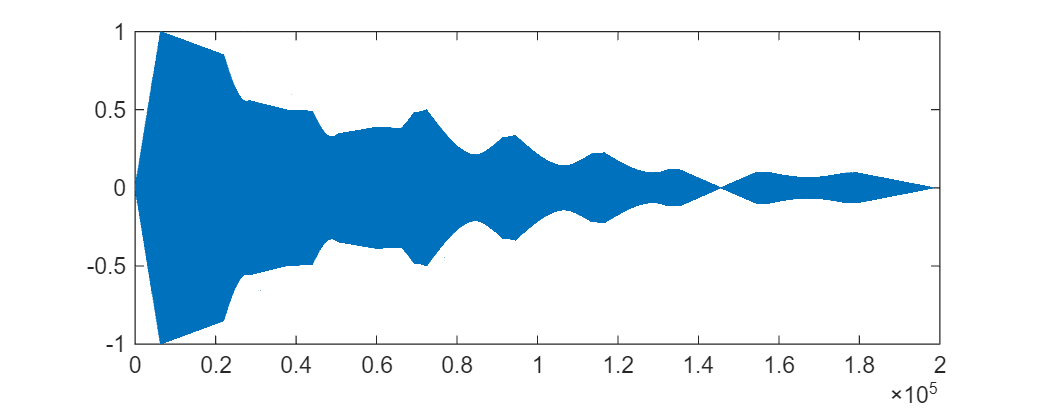

plot(delays)

% sound(delays,fs)

2. Compressor (Compressor)

Role: Reduce the dynamic range of audio, make the sound more compact, increase the thickness of the sound, sound more forward, able to top out

Principle: amplitude exceeds the threshold when the proportional compression, but in order to retain the beginning of the need to set the gradual start time, in order to maintain coherence and increase the end of the need to set the gradual release time.

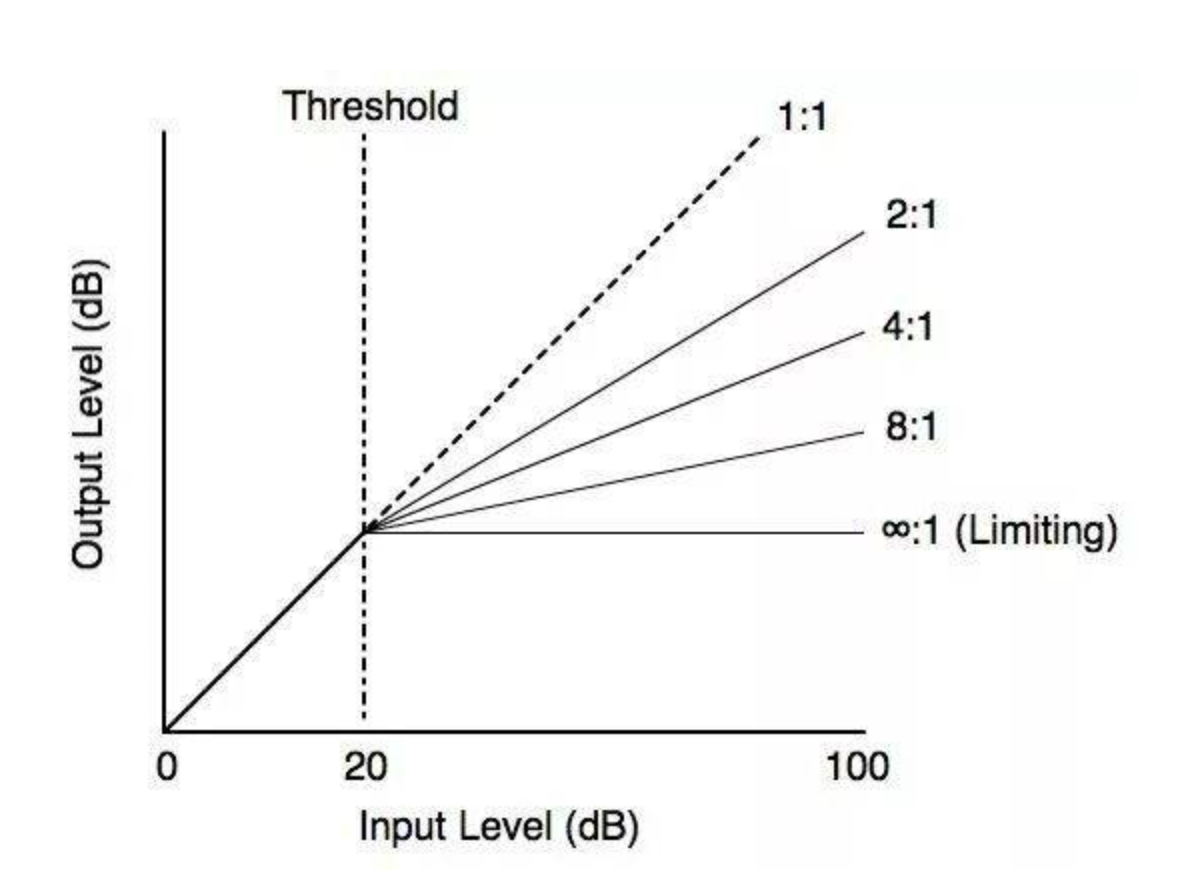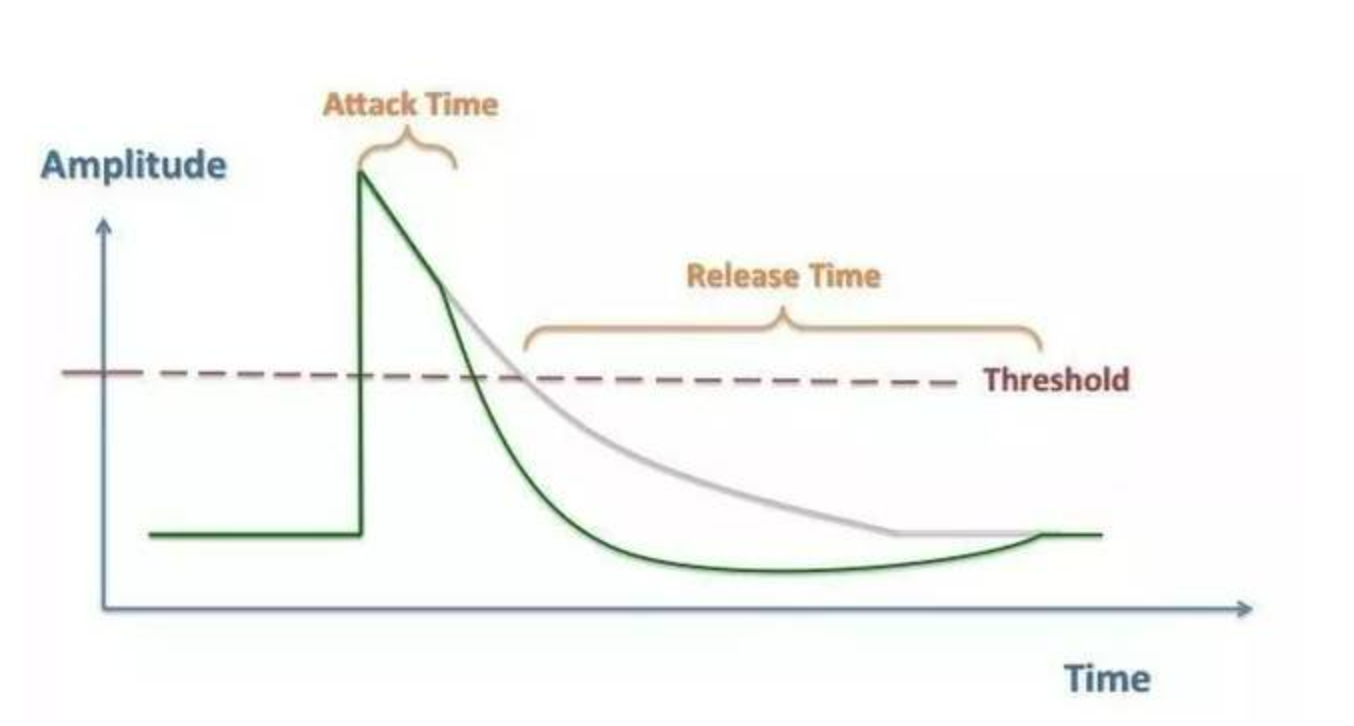

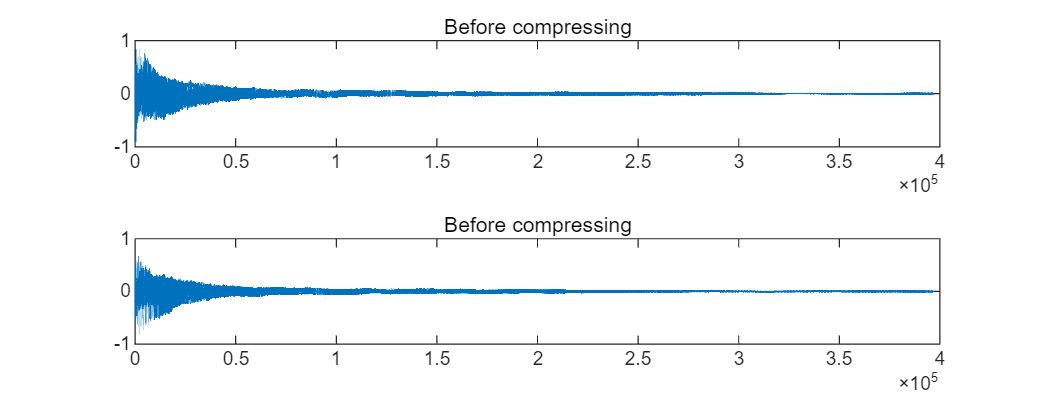

A=audioread('钢琴 88\German Concert D 050 083.wav')';
clf
subplot(2,1,1),plot(A(1,:)),title('Before compressing')
subplot(2,1,2),plot(A(2,:)),title('Before compressing')

help Compressor

 Compressor
 Input
  s - Original Signal
  Threshold - (0~1)
  Radio - (%)
  Attack - (ms)
  Release - (ms)
  Gain - (%)
  Wet - (%)



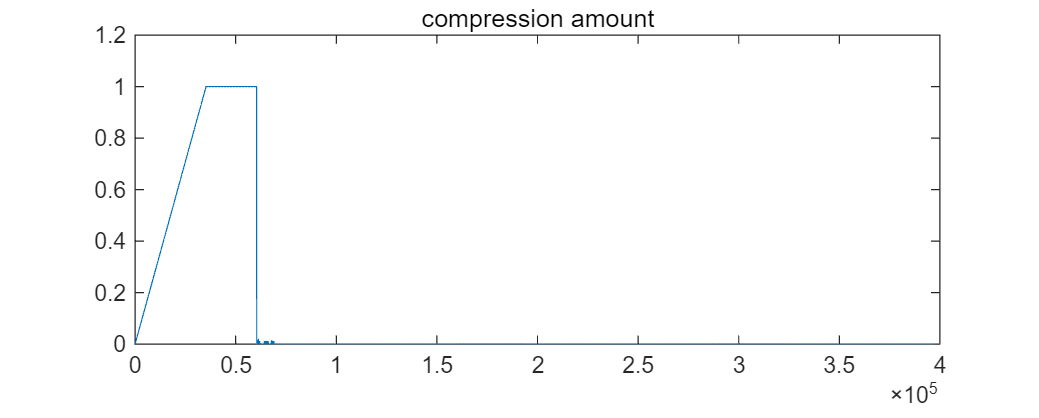

[s1,p]=Compressor(A,0.2,200,800,1,0,100);
s1=s1./max(abs(s1(:)));
sound(s1,44100)
clf,plot(p),title('compression amount')

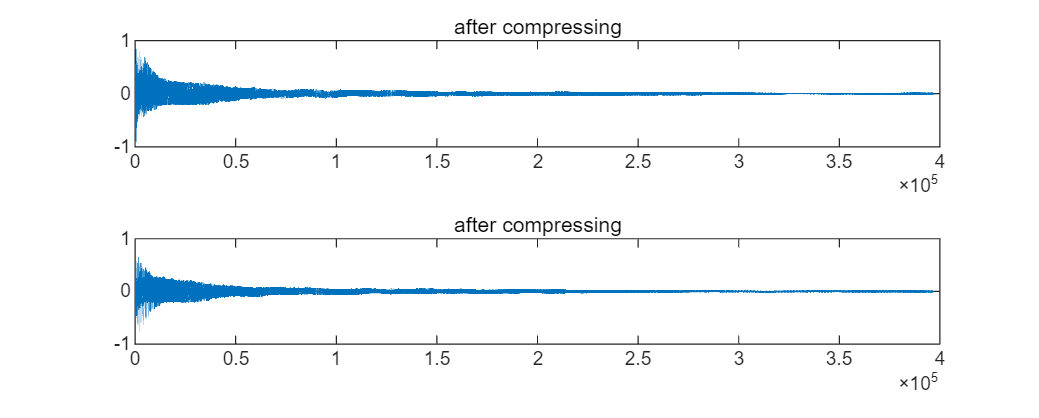

subplot(2,1,1),plot(s1(1,:)),title('after compressing')
subplot(2,1,2),plot(s1(2,:)),title('after compressing')

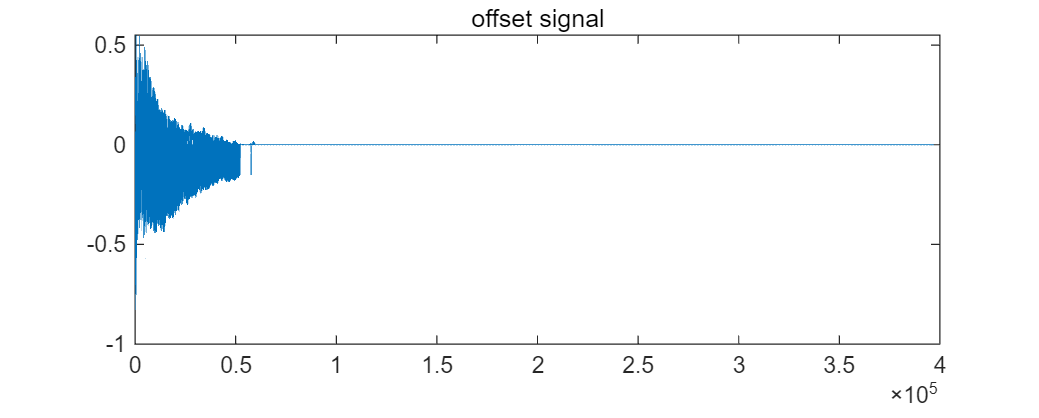

s=A;Threshold=0.1;Ratio=4;
offsets=(s>Threshold).*(s-(Threshold)).*(1-1/Ratio)...
    +(s<-Threshold).*(s-(Threshold)).*(1-1/Ratio);
clf,plot(offsets(1,:)),title('offset signal')

The dynamics of the piano sound are reduced, but there is distortion in the middle.

It is difficult to design this compressor, and to smooth out the compression (over a fairly long time frame)

Functions with Audio Toolbox

% help compressor

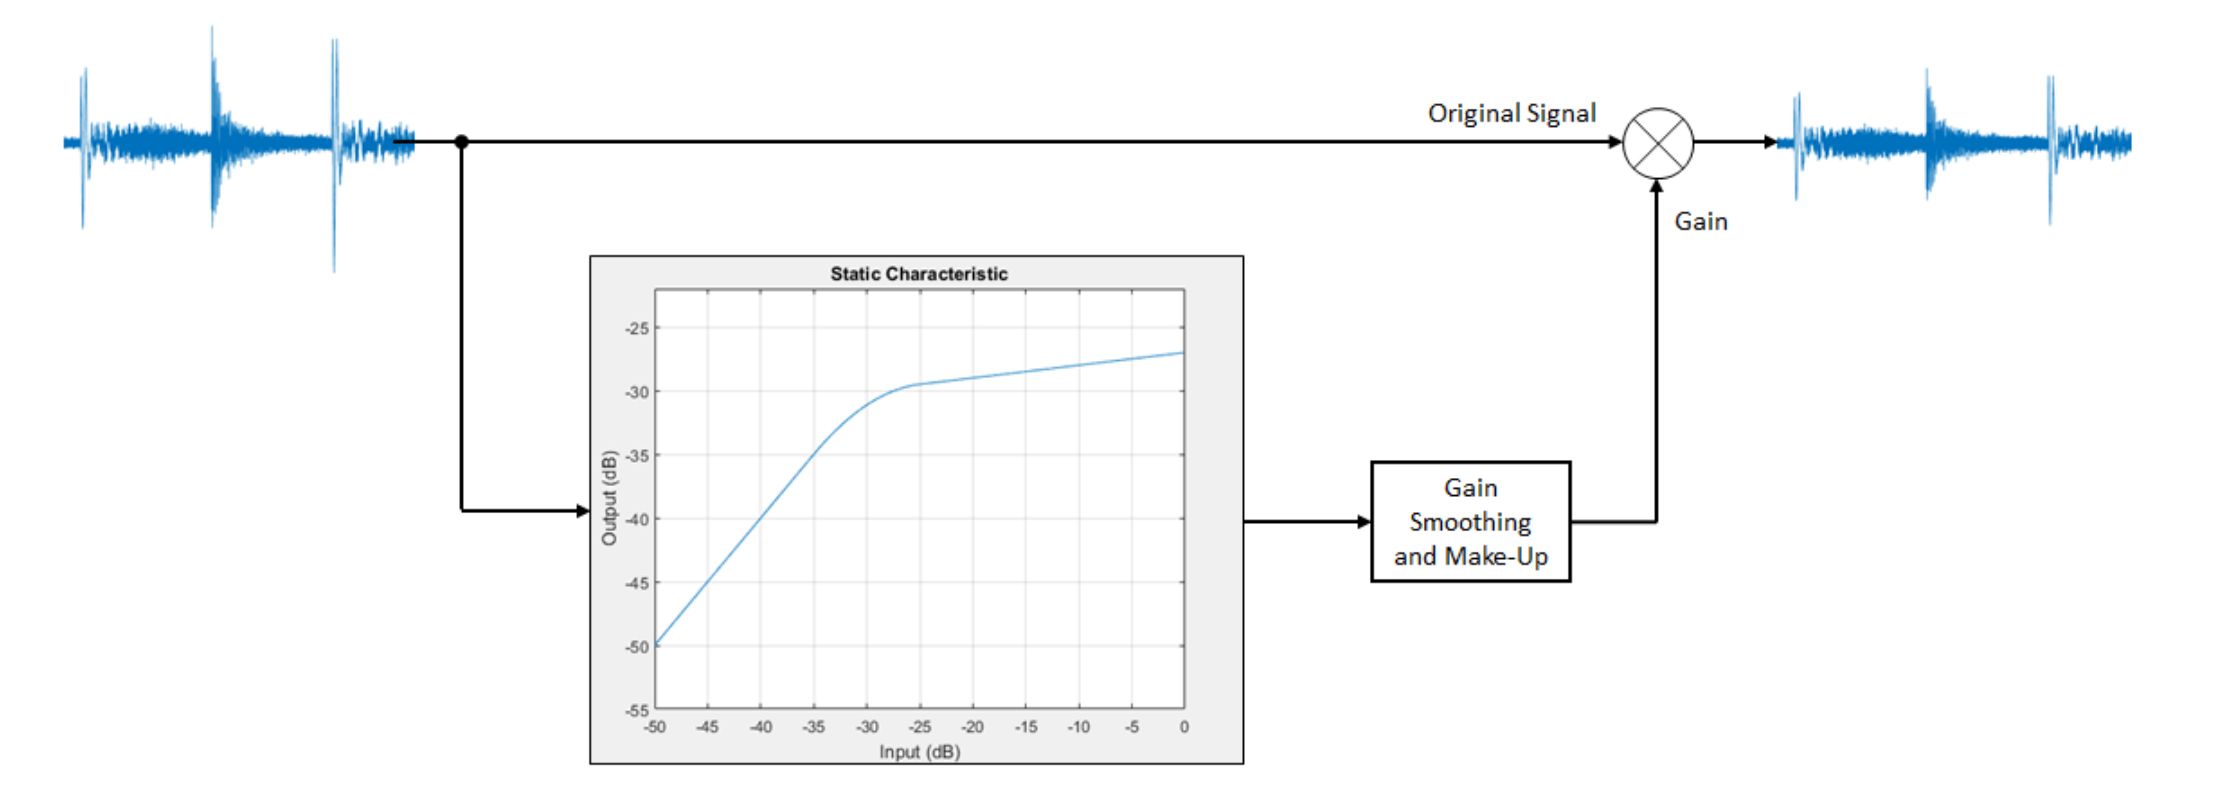

A=audioread('钢琴 88\German Concert D 050 083.wav')';
dRC=compressor;
dRC.Ratio=10;
dRC.Threshold=-15;
% dRC.MakeUpGain=3;
dRC.ReleaseTime=0.3

dRC =   compressor - 属性:

          Threshold: -15
              Ratio: 10
          KneeWidth: 0
         AttackTime: 0.0500
        ReleaseTime: 0.3000
     MakeUpGainMode: 'Property'
         MakeUpGain: 0
    EnableSidechain: false
         SampleRate: 44100

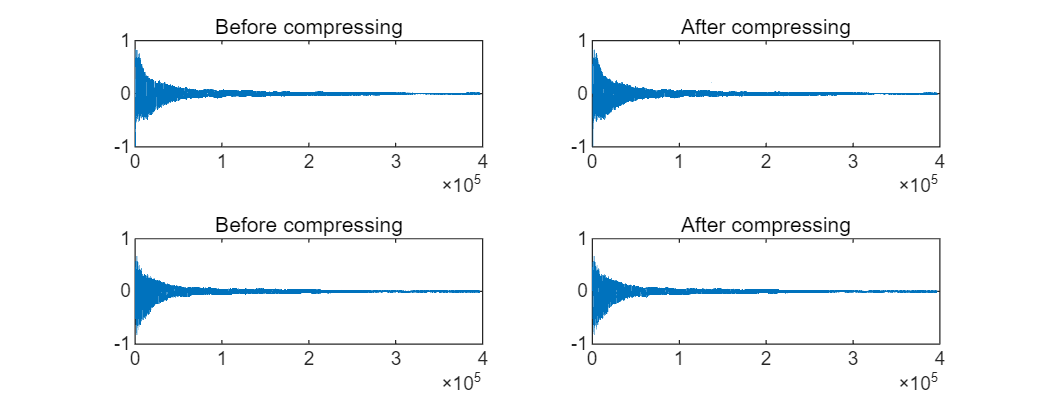

s=dRC(A);clf
subplot(2,2,1),plot(A(1,:)),title('Before compressing');subplot(2,2,2),plot(s(1,:)),title('After compressing');
subplot(2,2,3),plot(A(2,:)),title('Before compressing');subplot(2,2,4),plot(s(2,:)),title('After compressing')

% sound(s,fs)

3. Reverb effector (reverb)

Role: to increase the sense of space, enhance the texture

% help reverberator
A=audioread('钢琴 88\German Concert D 050 083.wav')';
reverb=reverberator

reverb =   reverberator - 属性:

                PreDelay: 0
        HighCutFrequency: 20000
               Diffusion: 0.5000
             DecayFactor: 0.5000
    HighFrequencyDamping: 5.0000e-04
               WetDryMix: 0.3000
              SampleRate: 44100

reverb.HighCutFrequency=16000;
s=reverb(A')';
sound(s,fs)

4. Limiter

The principle and the compressor is similar, do not let the total level exceed 0dB, 

otherwise in the audio output and playback will produce signal loss or clipping and distortion and so on.

% help limiter
L1=limiter

L1 =   limiter - 属性:

          Threshold: -10
          KneeWidth: 0
         AttackTime: 0
        ReleaseTime: 0.2000
     MakeUpGainMode: 'Property'
         MakeUpGain: 0
    EnableSidechain: false
         SampleRate: 44100

5. Equalizer & filter 

Creating a function to adjust the EQ

ans =   2×1 Line 数组:

  Line
  Line

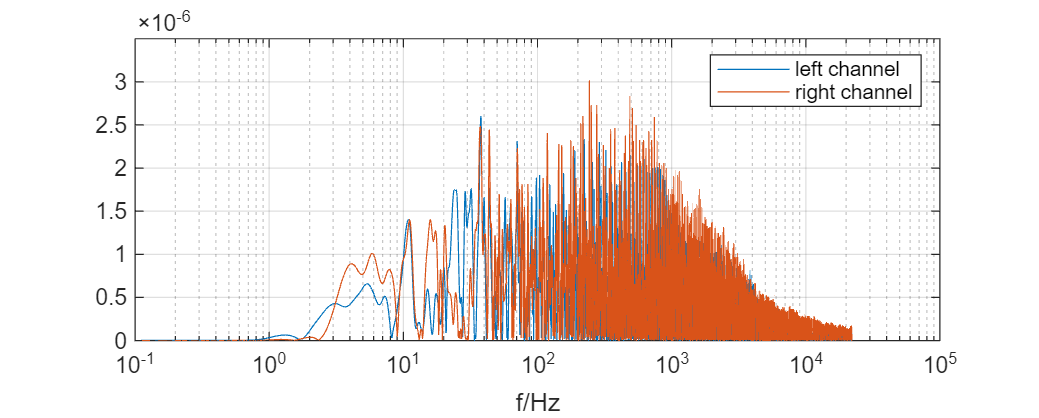

clf,frequency(A),legend('left channel','right channel')

ans =   2×1 Line 数组:

  Line
  Line

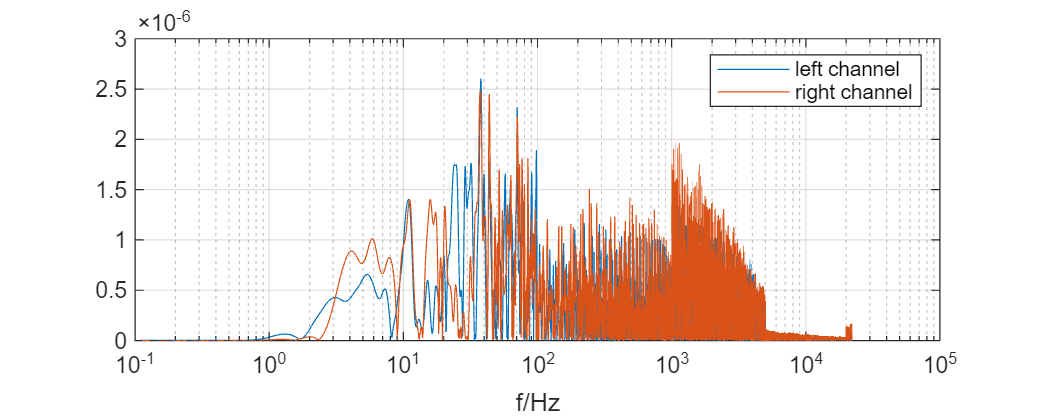

At=Equalizer(A,[100 1000 5000 20000],[-50 -80]);
%50% attenuation in the 100 to 1000 Hz range and 80% attenuation in the 5000 to 20,000 Hz range
frequency(At),legend('left channel','right channel')

%sound(At,fs)

Equalizers make it possible to attenuate or boost different frequencies, making the music more layered, and blending and avoiding frequencies between instruments, making the music more natural and coherent.

% help audiopluginexample.HighpassIIRFilter
% help multibandParametricEQ
mPEQ = multibandParametricEQ

mPEQ =   multibandParametricEQ - 属性:

       Frequencies: [100 181 325]
    QualityFactors: [1.6000 1.6000 1.6000]
         PeakGains: [0 0 0]
        SampleRate: 44100
        Oversample: false

mPEQ.Frequencies=[150 500 1000];%150Hz、500Hz、100Hz
mPEQ.PeakGains=[-10 -10 20];
%sound(A,fs)
A

A =          0         0         0         0    0.0001    0.0002    0.0002    0.0003    0.0004    0.0004    0.0006    0.0013    0.0027    0.0053    0.0081    0.0097    0.0104    0.0101    0.0084    0.0053    0.0007   -0.0057   -0.0146   -0.0255   -0.0373   -0.0502   -0.0643   -0.0802   -0.0976   -0.1158   -0.1346   -0.1531   -0.1700   -0.1857   -0.2000   -0.2125   -0.2235   -0.2337   -0.2432   -0.2514   -0.2585   -0.2637   -0.2671   -0.2683   -0.2676   -0.2661   -0.2649   -0.2655   -0.2686   -0.2746
         0         0         0         0   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0004   -0.0013   -0.0035   -0.0076   -0.0121   -0.0146   -0.0150   -0.0128   -0.0076         0    0.0089    0.0187    0.0297    0.0398    0.0464    0.0504    0.0524    0.0519    0.0480    0.0406    0.0300    0.0160         0   -0.0173   -0.0353   -0.0524   -0.0670   -0.0789   -0.0875   -0.0921   -0.0927   -0.0896   -0.0840   -0.0766   -0.0677   -0.0583   -0.0491   -0.0411   -0.0345   -0

At(1,:)=mPEQ(A(1,:)')';
At(2,:)=mPEQ(A(2,:)')'

At =          0         0         0         0    0.0001    0.0002    0.0002    0.0004    0.0005    0.0006    0.0008    0.0016    0.0034    0.0065    0.0102    0.0130    0.0149    0.0155    0.0142    0.0110    0.0053   -0.0032   -0.0155   -0.0313   -0.0493   -0.0698   -0.0925   -0.1181   -0.1460   -0.1753   -0.2054   -0.2350   -0.2623   -0.2868   -0.3078   -0.3245   -0.3366   -0.3447   -0.3487   -0.3480   -0.3428   -0.3323   -0.3167   -0.2957   -0.2698   -0.2406   -0.2097   -0.1799   -0.1526   -0.1294
   -0.0002   -0.0004   -0.0005   -0.0007   -0.0010   -0.0012   -0.0013   -0.0015   -0.0015   -0.0016   -0.0019   -0.0029   -0.0056   -0.0105   -0.0164   -0.0208   -0.0229   -0.0218   -0.0167   -0.0078    0.0040    0.0183    0.0353    0.0525    0.0667    0.0780    0.0864    0.0908    0.0898    0.0827    0.0694    0.0494    0.0240   -0.0059   -0.0392   -0.0737   -0.1068   -0.1373   -0.1635   -0.1836   -0.1965   -0.2017   -0.1998   -0.1914   -0.1766   -0.1566   -0.1328   -0.1067   -0.0795   -

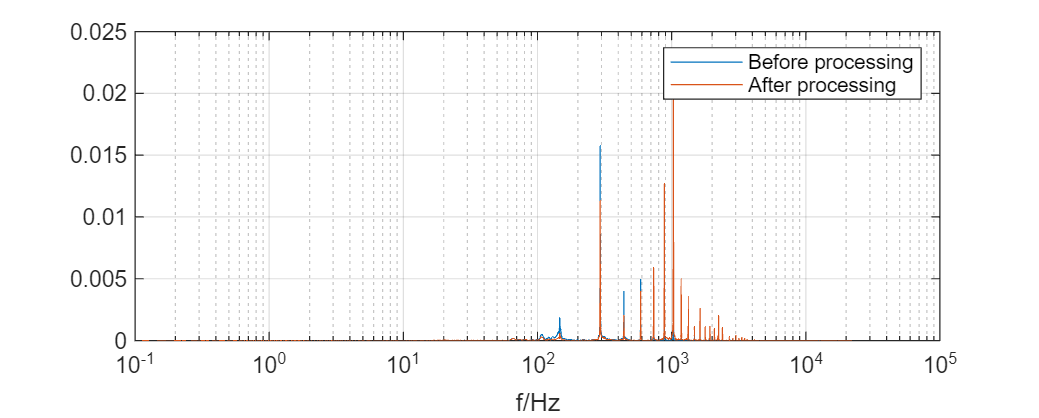

% sound(At,fs)
clf,
frequency(A(1,:));,hold on,frequency(At(1,:));hold off,legend('Before processing','After processing')

#### **Part III: Reading midi files**

The midi files are edited by DAW and the midi files can be transformed into Matlab arrays of structures. 

Record the score by extracting key information from the midi file

mididata=(midinote, velocity, deltatick, cumulativeTick ,start/end)

**Pitch, intensity, number of interval ticks, cumulative ticks, start/end**